# Tutorial04 Simulating and Imaging Randomly Diffusing Molecules

#### Notes

Note.

Save all my code. They will be reused and build on each other.

Objective: To be more famiiar with Matrix multiplications through a variation of a random walk.

2. Simulating a Random Walk in 1D

1.. Initialize two matrices

% Parameters
L = 500

L = 500

n_particle = 500

n_particle = 500

n_kicks = 10000

n_kicks = 10000


f = zeros(n_kicks, n_particle);
x = zeros(n_kicks, n_particle);

2.. Assign the initial particle positions in f(1, :) such that the n_p particles are uniformly disributed across the Universe.

% Initially did
% f(1,:) = length*rand(1, n_particle)

% After reaching step 5, for convenience, decided to refer to the solution.
f(1,:) = randperm(L)

f =    131   247   483   448   205   252   458   474   103   451   293   374   237   319   234   211   250   300   100   120   317   217   176   106   201   188   346   461   324   309   134   275    32   115   413   439   421   296   491   184     1   231   109   347   161   377   375   427   189    55
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

3.. Store displacement of each kick.

Received help from solution doc.

% Assign kicks at each time step.
f(2:end,:) = randn(n_kicks-1, n_particle)

f =   131.0000  247.0000  483.0000  448.0000  205.0000  252.0000  458.0000  474.0000  103.0000  451.0000  293.0000  374.0000  237.0000  319.0000  234.0000  211.0000  250.0000  300.0000  100.0000  120.0000  317.0000  217.0000  176.0000  106.0000  201.0000  188.0000  346.0000  461.0000  324.0000  309.0000  134.0000  275.0000   32.0000  115.0000  413.0000  439.0000  421.0000  296.0000  491.0000  184.0000    1.0000  231.0000  109.0000  347.0000  161.0000  377.0000  375.0000  427.0000  189.0000   55.0000
   -1.4175    0.9228    0.9221    0.7497   -0.4636   -0.2023   -1.0872    1.6161    0.1173    1.5462    1.2803    1.3690    0.3727   -0.7959    0.5558   -0.7186   -0.9111   -0.4226   -2.4012    1.7919   -2.3060    0.4993   -0.6093    0.4526   -0.2377    0.2477    1.1654    0.9521   -1.2097   -0.5228    1.9723   -1.8515    0.4630    3.7160   -0.4377   -0.3874    0.8616    1.3096   -1.0721   -2.3013    0.5024   -0.9386    0.6100   -1.2419   -0.5510   -0.0075    0.3436   -2.0228   -0.1103   -0

Note. Difference between **rand** and **randn**.

**rand**: uniformly distributed random numbers. Returns random #s between 0 and 1 from uniform distribution.

**randn**: normally(Gaussian) distributed random numbers. Returns random #s of mean 0 and variance 1.

4.. Assign x to the particle trajectories. Use **cumsum** and mod.

% help cumsum
% stepx = cumsum(-1+2*stepx)
x = cumsum(f)

x =   131.0000  247.0000  483.0000  448.0000  205.0000  252.0000  458.0000  474.0000  103.0000  451.0000  293.0000  374.0000  237.0000  319.0000  234.0000  211.0000  250.0000  300.0000  100.0000  120.0000  317.0000  217.0000  176.0000  106.0000  201.0000  188.0000  346.0000  461.0000  324.0000  309.0000  134.0000  275.0000   32.0000  115.0000  413.0000  439.0000  421.0000  296.0000  491.0000  184.0000    1.0000  231.0000  109.0000  347.0000  161.0000  377.0000  375.0000  427.0000  189.0000   55.0000
  129.5825  247.9228  483.9221  448.7497  204.5364  251.7977  456.9128  475.6161  103.1173  452.5462  294.2803  375.3690  237.3727  318.2041  234.5558  210.2814  249.0889  299.5774   97.5988  121.7919  314.6940  217.4993  175.3907  106.4526  200.7623  188.2477  347.1654  461.9521  322.7903  308.4772  135.9723  273.1485   32.4630  118.7160  412.5623  438.6126  421.8616  297.3096  489.9279  181.6987    1.5024  230.0614  109.6100  345.7581  160.4490  376.9925  375.3436  424.9772  188.8897   54

x = mod(x, 500)

x =   131.0000  247.0000  483.0000  448.0000  205.0000  252.0000  458.0000  474.0000  103.0000  451.0000  293.0000  374.0000  237.0000  319.0000  234.0000  211.0000  250.0000  300.0000  100.0000  120.0000  317.0000  217.0000  176.0000  106.0000  201.0000  188.0000  346.0000  461.0000  324.0000  309.0000  134.0000  275.0000   32.0000  115.0000  413.0000  439.0000  421.0000  296.0000  491.0000  184.0000    1.0000  231.0000  109.0000  347.0000  161.0000  377.0000  375.0000  427.0000  189.0000   55.0000
  129.5825  247.9228  483.9221  448.7497  204.5364  251.7977  456.9128  475.6161  103.1173  452.5462  294.2803  375.3690  237.3727  318.2041  234.5558  210.2814  249.0889  299.5774   97.5988  121.7919  314.6940  217.4993  175.3907  106.4526  200.7623  188.2477  347.1654  461.9521  322.7903  308.4772  135.9723  273.1485   32.4630  118.7160  412.5623  438.6126  421.8616  297.3096  489.9279  181.6987    1.5024  230.0614  109.6100  345.7581  160.4490  376.9925  375.3436  424.9772  188.8897   54

**cumsum**: cumulative sum of elements. Check documentation how it works for a matrix.

Sample Code

`Cumsum of each column`

`A = [1 4 7; 2 5 8; 3 6 9]`

`A = `*3×3*

`     1     4     7`

`     2     5     8`

`     3     6     9`

`B = cumsum(A)`

`B = ``3×3`

`     1     4     7`

`     3     9    15`

`     6    15    24`

`Cumsum of each row`

`A = [1 3 5; 2 4 6]`

`A = ``2×3`

`     1     3     5`

`     2     4     6`

`B = cumsum(A,2)`

`B = ``2×3`

`     1     4     9`

`     2     6    12`

**mod**: Takes mod. 

Sample code.

q = [0:10] 

mod(q,5)

mod(q,4)

Q = [0:10;0:10;0:10] 

mod(Q,5) 

mod(Q,2)

Here, mod is used to ensure the particles stay in the universe.

5.. Visualizing particle trajectories by creating an *image*.

I(x,t). corresponds to the # of particles at location x at time t. 

Image: a matrix that represents the grid of pixels, whose entires contain some info about those pixels - here, it's intensity. c.f. The higher the count of a pixel, the brighter it'll be.

% first, use ceiling to discretize x.
x = ceil(x)

x =    131   247   483   448   205   252   458   474   103   451   293   374   237   319   234   211   250   300   100   120   317   217   176   106   201   188   346   461   324   309   134   275    32   115   413   439   421   296   491   184     1   231   109   347   161   377   375   427   189    55
   130   248   484   449   205   252   457   476   104   453   295   376   238   319   235   211   250   300    98   122   315   218   176   107   201   189   348   462   323   309   136   274    33   119   413   439   422   298   490   182     2   231   110   346   161   377   376   425   189    55
   131   249   483   449   206   251   457   477   105   453   296   376   238   318   234   211   249   301    96   122   316   220   176   108   203   189   348   463   322   308   137   272    35   117   412   438   423   297   490   181     2   233   111   345   162   377   375   424   189    55
   131   249   483   450   204   250   457   479   105   454   297   375   237   318   234   


% create image to store result.
% initialize image
I = zeros(L, n_kicks)

I =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   


% for each number from 1 to 500, count the occurence and store in the matrix.
for n = 1:n_kicks
    % disp(n)
    location_ranges = 1:500;
    [counts, ind] = histc(x(n, :), location_ranges);
    % transpose(counts)
    I(:, n) = transpose(counts);  % can use " counts.' "
end

I

I =      1     0     0     1     0     0     0     1     0     0     0     0     0     0     0     0     0     0     1     1     0     0     0     0     0     0     0     2     0     1     0     0     1     0     0     1     1     1     1     1     0     0     0     1     1     0     1     2     1     2
     1     2     1     0     1     1     1     1     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     1     0     1     1     0     1     1     0     0     0     0     2     1     0     0     0     0     1     0     1     2     0
     1     0     1     2     1     1     1     1     0     0     0     0     0     1     2     0     0     0     0     0     0     0     0     0     0     1     1     0     0     0     0     0     0     0     0     0     1     1     1     0     0     0     0     0     0     0     0     0     0     1
     1     1     1     1     3     2     1     1     1     1     1     1     1     1     0   

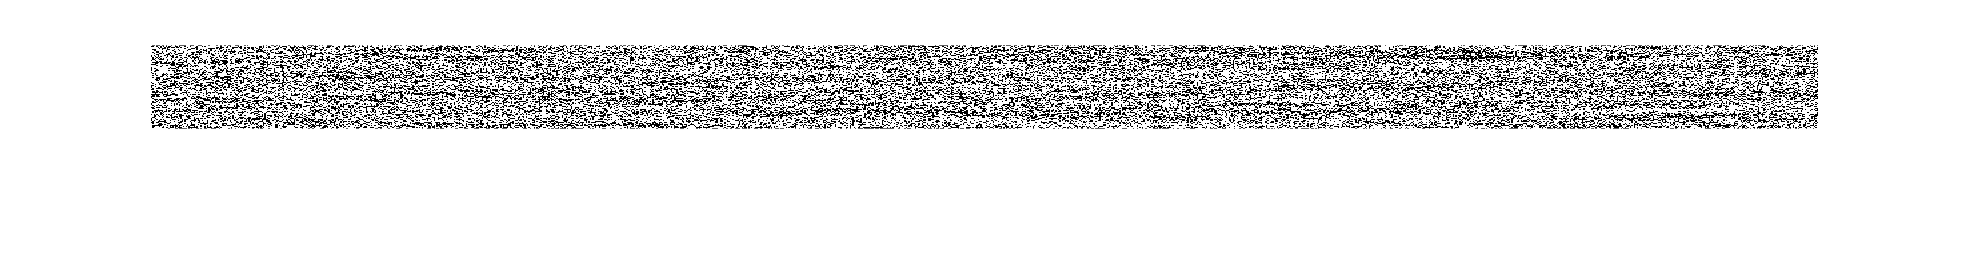

%groupcounts(x)

imshow(I)

Original image

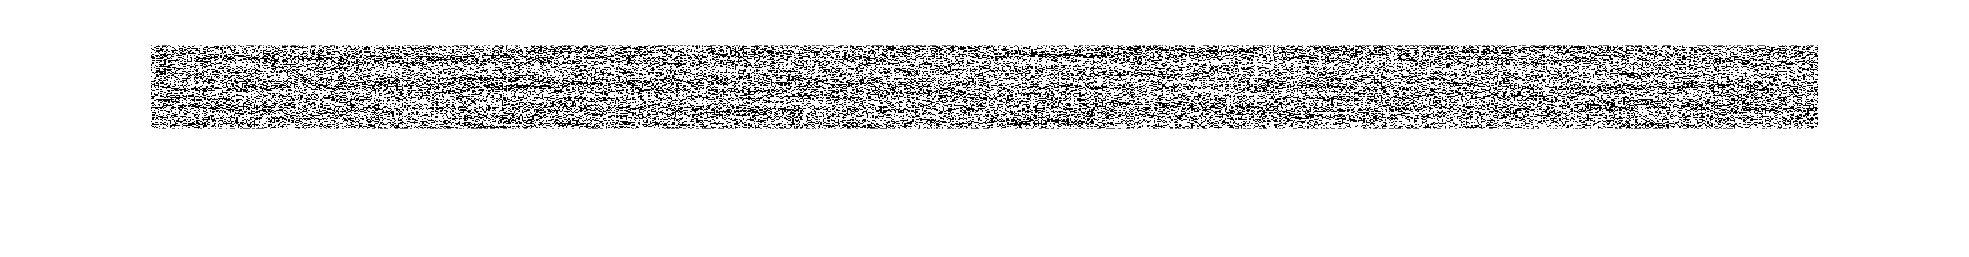

Choosing subsection of the matrix and showing it.

I_section = I(:, 3:950)

I_section =      0     1     0     0     0     1     0     0     0     0     0     0     0     0     0     0     1     1     0     0     0     0     0     0     0     2     0     1     0     0     1     0     0     1     1     1     1     1     0     0     0     1     1     0     1     2     1     2     2     1
     1     0     1     1     1     1     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     1     0     1     1     0     1     1     0     0     0     0     2     1     0     0     0     0     1     0     1     2     0     0     0
     1     2     1     1     1     1     0     0     0     0     0     1     2     0     0     0     0     0     0     0     0     0     0     1     1     0     0     0     0     0     0     0     0     0     1     1     1     0     0     0     0     0     0     0     0     0     0     1     1     1
     1     1     3     2     1     1     1     1     1     1     1     1     0     2 

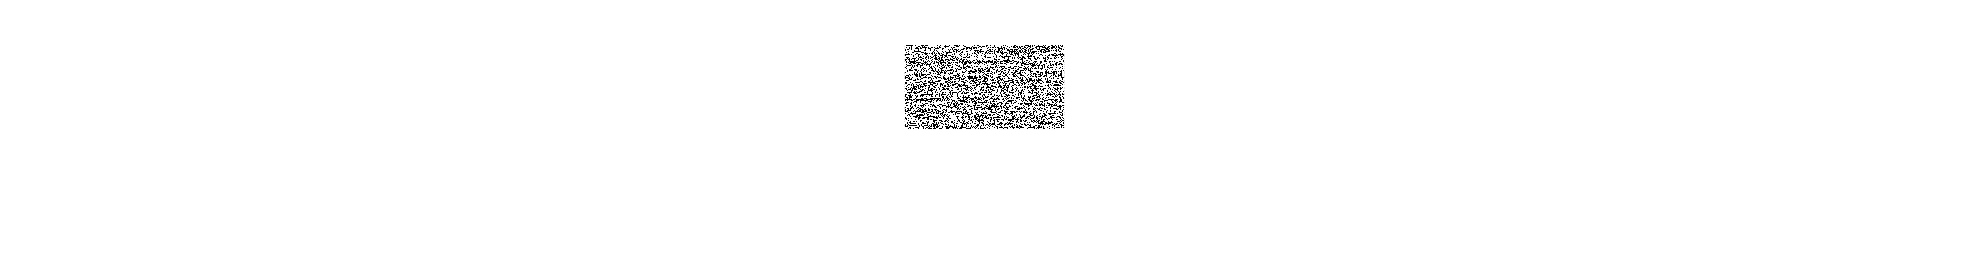

imshow(I_section)

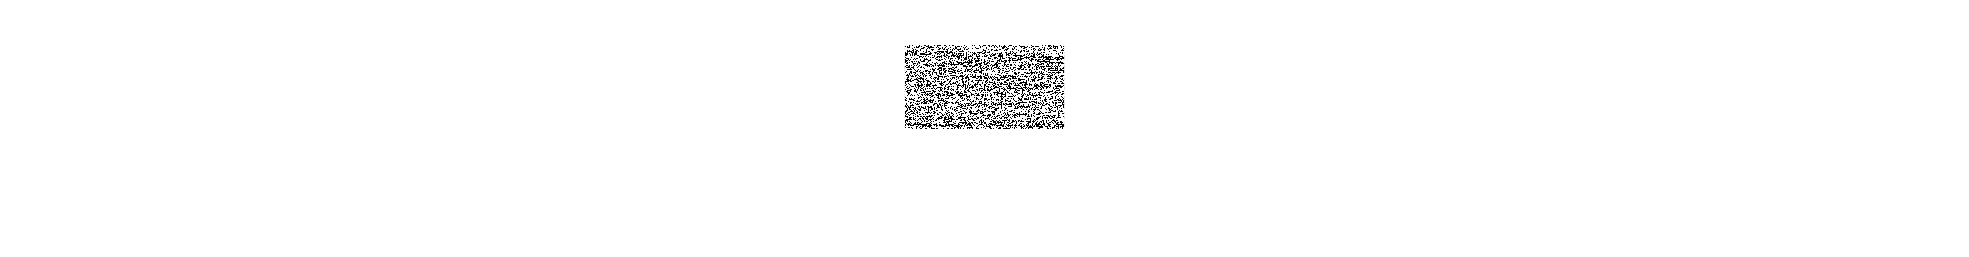

6.. Calculate the variance in positions sampled by each particle.

var_particles = var(transpose(I))

var_particles =     1.0337    1.0262    1.0767    1.0549    1.0587    1.0706    1.0195    1.0156    1.0334    0.9647    0.9792    0.9362    0.9587    0.9175    0.9168    0.8959    0.9276    0.8817    0.9068    0.9168    0.9765    0.9338    0.9309    0.9537    0.9109    0.9556    0.9713    0.9271    0.8900    0.8902    0.9316    0.9132    0.9261    0.9230    0.9324    0.9199    0.8865    0.8979    0.9088    0.8964    0.9177    0.9594    0.9767    0.9855    0.9523    0.9591    0.9230    0.9347    0.9315    0.9716



% Avg value for variance over all particles:
[temp, arrL] = size(var_particles)

temp = 1

arrL = 500

avg_variance = mean(sum(var_particles)) / arrL

avg_variance = 0.9938

The average value for variance over all particles, after a couple of runs of the program, was very close to 1: e.g. 0.9861, 0.9894, 0.9938. This IS what we expect, because the values are pretty much 1, and the kicks were Gaussian-distributed, which means it has variance 1.